## Analysis Pipeline for PEP WP-4 fMRI Project

### House keeping

clc; clear; %close all;%dbstop if error;
cfg = struct;
d = struct;

% add functions folder to path
cfg.functionPath = fullfile(pwd,'utilities');
addpath(genpath(cfg.functionPath))


### Define to-be-analyzed subjects

cfg.subNums = [101:117, 119:124, 126:130, 132, 133]; % 118, 125, and 131 did not finish the experiment
cfg = defaultCfg(cfg);


### Preprocessing

This cannot be replicated as raw anatomical scans cannot be shared to protect participants privacy. Preprocessed files can be found on the OSF page. 

% disp(['Running pre-processing...' newline]);
% preproc_func(cfg);


Running pre-processing...



Preprocessed data for subject 101 exists already
Preprocessed data for subject 102 exists already
Preprocessed data for subject 103 exists already
Preprocessed data for subject 104 exists already
Preprocessed data for subject 105 exists already
Preprocessed data for subject 106 exists already
Preprocessed data for subject 107 exists already
Preprocessed data for subject 108 exists already
Preprocessed data for subject 109 exists already
Preprocessed data for subject 110 exists already
Preprocessed data for subject 111 exists already
Preprocessed data for subject 112 exists already
Preprocessed data for subject 113 exists already
Preprocessed data for subject 114 exists already
Preprocessed data for subject 115 exists already
Preprocessed data for subject 116 exists already
Preprocessed data for subject 117 exists already
Preprocessed data for subject 119 exists already
Preprocessed data for subject 120 exists already
Preprocessed data for subject 121 exists already
Preprocessed data fo

### Define functional ROIs using localizer

disp(['Get functional ROIs...' newline]);
level1_glm_norm_func(cfg)

cfg.func_roi_names = {'PPA', 'TOS', 'RSC', 'LOC', 'LPFC'};

Get functional ROIs...



cfg.n_voxels = 200;

Starting first level glm in SPM for subject 101
Data for subject 101 exists already
Starting first level glm in SPM for subject 102
Data for subject 102 exists already
Starting first level glm in SPM for subject 103
Data for subject 103 exists already
Starting first level glm in SPM for subject 104
Data for subject 104 exists already
Starting first level glm in SPM for subject 105
Data for subject 105 exists already
Starting first level glm in SPM for subject 106
Data for subject 106 exists already
Starting first level glm in SPM for subject 107
Data for subject 107 exists already
Starting first level glm in SPM for subject 108
Data for subject 108 exists already
Starting first level glm in SPM for subject 109
Data for subject 109 exists already
Starting first level glm in SPM for subject 110
Data for subject 110 exists already
Starting first level glm in SPM for subject 111
Data for subject 111 exists already
Starting first level glm in SPM for subject 112
Data for subject 112 exists 

funcROIs(cfg)


### Get inter-subject similarity on drawings

cfg.dnn = 'vgg16_imagenet';

    Saved functional ROI for PPA to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-101\PPA_funcROI.nii
    Saved functional ROI for TOS to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-101\TOS_funcROI.nii
    Saved functional ROI for RSC to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-101\RSC_funcROI.nii
    Saved functional ROI for LOC to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-101\LOC_funcROI.nii
    Saved functional ROI for PPA to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-102\PPA_funcROI.nii
    Saved functional ROI for TOS to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pe

    Saved functional ROI for LPFC to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-101\LPFC_funcROI.nii
    Saved functional ROI for LPFC to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-102\LPFC_funcROI.nii
    Saved functional ROI for LPFC to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-103\LPFC_funcROI.nii
    Saved functional ROI for LPFC to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-104\LPFC_funcROI.nii
    Saved functional ROI for LPFC to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokumente\GitHub\pep_wp4_fMRI\code\..\MNI_ROIs\func_ROIs\sub-105\LPFC_funcROI.nii
    Saved functional ROI for LPFC to C:\Users\JLU-SU\OneDrive - Justus-Liebig-Universität Gießen\Dokument

cfg.layer_type = 'late';

Running pairwise decoding...



Running pairwise correlations...



cfg.correlation_type = 'Spearman';
cfg.dissimilarity = true;

% get images
cfg.analysis_names = {'typical', 'control','photos'};
images = load_images(cfg);

% typical images
cfg.analysis_name = 'typical';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

Loaded image: 101_bat_gen1.png
Loaded image: 101_bat_gen2.png
Loaded image: 101_bat_gen3.png
Loaded image: 102_bat_gen1.png
Loaded image: 102_bat_gen2.png
Loaded image: 102_bat_gen3.png
Loaded image: 103_bat_gen1.png
Loaded image: 103_bat_gen2.png
Loaded image: 103_bat_gen3.png
Loaded image: 104_bat_gen1.png
Loaded image: 104_bat_gen2.png
Loaded image: 104_bat_gen3.png
Loaded image: 105_bat_gen1.png
Loaded image: 105_bat_gen2.png
Loaded image: 105_bat_gen3.png
Loaded image: 106_bat_gen1.png
Loaded image: 106_bat_gen2.png
Loaded image: 106_bat_gen3.png
Loaded image: 107_bat_gen1.png
Loaded image: 107_bat_gen2.png
Loaded image: 107_bat_gen3.png
Loaded image: 108_bat_gen1.png
Loaded image: 108_bat_gen2.png
Loaded image: 108_bat_gen3.png
Loaded image: 109_bat_gen1.png
Loaded image: 109_bat_gen2.png
Loaded image: 109_bat_gen3.png
Loaded image: 110_bat_gen1.png
Loaded image: 110_bat_gen2.png
Loaded image: 110_bat_gen3.png
Loaded image: 111_bat_gen1.png
Loaded image: 111_bat_gen2.png
Loaded i


% control images
cfg.analysis_name = 'control';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

analysis typical - layer #1 - category: bathroom
analysis typical - layer #1 - category: kitchen



% photos
cfg.analysis_name = 'photos';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

analysis control - layer #1 - category: bathroom
analysis control - layer #1 - category: kitchen



% filter for included subjects
d = filterCurrentSubs(d, cfg)


analysis photos - layer #1 - category: bathroom
analysis photos - layer #1 - category: kitchen


## **Get inter-subject similarity on timecourses**

% preparation
cfg.dissimilarity = true;

d = struct with fields:
    bathroom_RDM: [1×1 struct]
     kitchen_RDM: [1×1 struct]
             DNN: [1×1 struct]


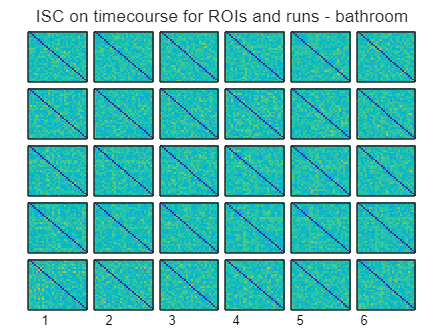

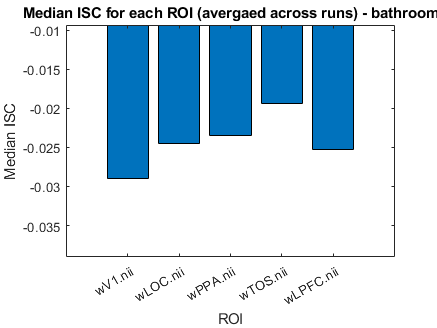

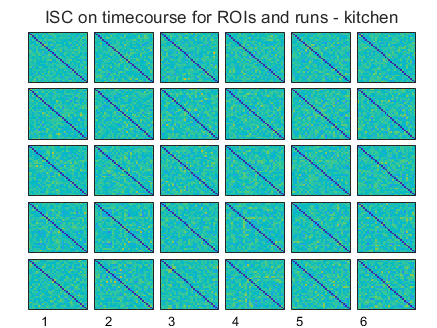

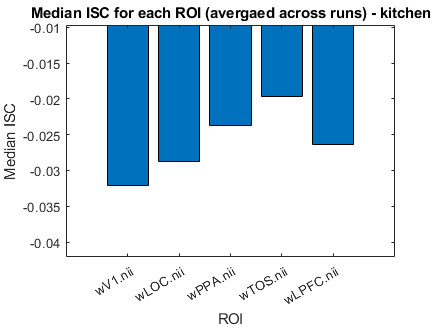

cfg.plotting = true;
cfg.rois = {'wV1.nii', 'wLOC.nii',...
     'wPPA.nii', 'wTOS.nii',...
     'wLPFC.nii'};

% get timecourses (average Voxels for each ROI)
cfg.skipIfExists = true; % this uses the previously extracted time courses. Put to false to repeat that step.
cfg.smoothing = false; 
cfg.saveWholeBrain = false;
cfg.cutTargets = false;
averageVoxelsInROI(cfg)

% get ISC from timecourses
cfg.plotting = true;
cfg.plot_rdm = false;
cfg.partial_cor = false;
cfg.regressOutMean = true;
cfg.detrend = true;
cfg.correlation_type = 'Pearson';
d = neural_timecourse_intersub_cor(d, cfg);

% get split-half reliability for ISC
cfg.permutation_test = true;
cfg.n_permutations = 10000;
d = splithalfReliabilityISC(d, cfg);

### **Compare ISC from drawings with timecourse ISC**

% preparation
cfg.partial_cor = true;
cfg.plotting = true;
cfg.plot_rdm = false;
cfg.predictor_RDMs = {'typical_late', 'control_late', 'photos_late'};
cfg.RDM_to_partial_out = cfg.predictor_RDMs;
cfg.rois_of_interest = {'V1', 'LOC',...
    'PPA', 'TOS', 'LPFC'};
cfg.dnns = {'vgg16_imagenet'};
cfg.plot_type = 'violin';
cfg.show_single_cate = false;
cfg.permutation_test = true;
cfg.n_permutations = 10000;
cfg.permutation_type = 'row_col_shuffle_ref';
cfg.ISC_type = 'timecourseRDM';
cfg.partial_correlation_type = 'Spearman';

% plot typical drawings
cfg.plotting_predictors = 1;
d = compare_roi_RDMs_to_predictor_RDMs(d, cfg);

% plot condtrol predictors
cfg.plotting_predictors = [2,3];
d = compare_roi_RDMs_to_predictor_RDMs(d, cfg);

### **Whole brain parcel anaylsis**

 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of V1 bathroom is done
20% of permutations of V1 bathroom is done
30% of permutations of V1 bathroom is done
40% of permutations of V1 bathroom is done
50% of permutations of V1 bathroom is done
60% of permutations of V1 bathroom is done
70% of permutations of V1 bathroom is done
80% of permutations of V1 bathroom is done
90% of permutations of V1 bathroom is done
100% of permutations of V1 bathroom is done
Compare inter-subject RDM of V1 with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of V1 kitchen is done
20% of permutations of V1 kitchen is done
30% of permutations of V1 kitchen is done
40% of permutations of V1 kitchen is done
50% of permutations of V1 kitchen is done
60% of permutations of V1 kitchen is done
70% of permutations of V1 kitchen is done
80% of permutations of V1 kitchen is done
90% of permutations of V1 kitch

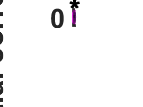

% preparation

 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of V1 bathroom is done
20% of permutations of V1 bathroom is done
30% of permutations of V1 bathroom is done
40% of permutations of V1 bathroom is done
50% of permutations of V1 bathroom is done
60% of permutations of V1 bathroom is done
70% of permutations of V1 bathroom is done
80% of permutations of V1 bathroom is done
90% of permutations of V1 bathroom is done
100% of permutations of V1 bathroom is done
Compare inter-subject RDM of V1 with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of V1 kitchen is done
20% of permutations of V1 kitchen is done
30% of permutations of V1 kitchen is done
40% of permutations of V1 kitchen is done
50% of permutations of V1 kitchen is done
60% of permutations of V1 kitchen is done
70% of permutations of V1 kitchen is done
80% of permutations of V1 kitchen is done
90% of permutations of V1 kitch

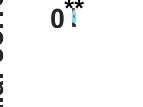

cfg.skipIfExists = true; 
cfg.regressOutMean = true;
cfg.detrend = true;
cfg.cutTargets = false; 

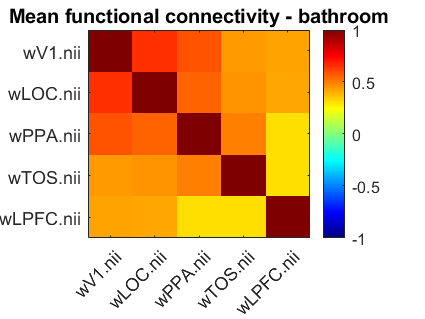

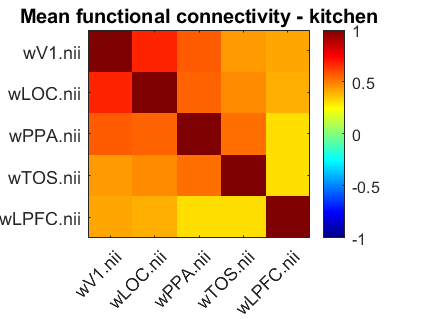

d = struct with fields:
                      pairRep: [1×1 struct]
                          DNN: [1×1 struct]
                 bathroom_RDM: [1×1 struct]
                  kitchen_RDM: [1×1 struct]
                 splitHalfISC: [1×1 struct]
     compare_roi_to_predictor: [1×1 struct]
    compare_task_to_predictor: [1×1 struct]
                           FC: [1×1 struct]


cfg.numVoxels = [1,2,5,10,20,50,100,200,500,1000,5000,inf];  % inf = all voxels
cfg.searchlightSource = 'HCP'; 
cfg.dnns = {'vgg16_imagenet'}; 

cfg.predictor_RDMs = {'typical_late','control_late','photos_late'}; 
cfg.partial_correlation_type = 'Pearson';

% get parcels avergae time courses
extract_parcel_timecourses(cfg)

% get ISC 
d = compute_ISC_parcels(cfg, d)

% compare parcel ISC to drawings
d.parcel_ISC = searchlight_parcel_ISC(cfg, d)


### Get inter-subject similarity on drawings for scene DNN

 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of allROIs bathroom is done
20% of permutations of allROIs bathroom is done
30% of permutations of allROIs bathroom is done
40% of permutations of allROIs bathroom is done
50% of permutations of allROIs bathroom is done
60% of permutations of allROIs bathroom is done
70% of permutations of allROIs bathroom is done
80% of permutations of allROIs bathroom is done
90% of permutations of allROIs bathroom is done
100% of permutations of allROIs bathroom is done
Compare inter-subject RDM of allROIs with partial correaltion of predictor RDMs - bathroom
 Start evaluating predictor RDMs
Predictor RDMs evaluated
10% of permutations of allROIs kitchen is done
20% of permutations of allROIs kitchen is done
30% of permutations of allROIs kitchen is done
40% of permutations of allROIs kitchen is done
50% of permutations of allROIs kitchen is done
60% of permutations of allROIs kitchen is done
70% of permutations of allROIs

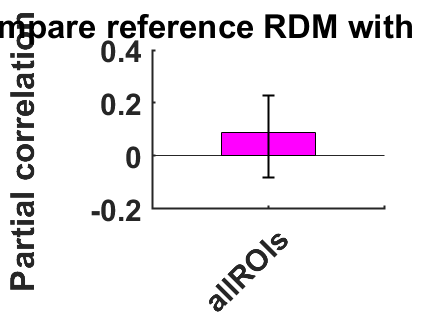

cfg.dnn = 'vggnet16_places365';
cfg.layer_type = 'late';
cfg.correlation_type = 'Spearman';
cfg.dissimilarity = true;


% typical images
cfg.analysis_name = 'typical';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

% control images
cfg.analysis_name = 'control';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

% photos
cfg.analysis_name = 'photos';
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);

% filter for included subjects
d = filterCurrentSubs(d, cfg)


% preparation
cfg.partial_cor = true;
cfg.plotting = true;
cfg.plot_rdm = false;
cfg.predictor_RDMs = {'typical_late', 'control_late', 'photos_late'};
cfg.RDM_to_partial_out = cfg.predictor_RDMs;
% cfg.rois_of_interest = {'V1', 'V2', ...
%     'LOC', 'PPA', 'TOS', 'RSC', 'LPFC',...
%     'motorCortex', 'S1', 'auditoryCortex'};
cfg.rois_of_interest = {'V1', 'LOC',...
    'PPA', 'TOS', 'LPFC'};
cfg.dnns = {cfg.dnn};
cfg.plot_type = 'violin';
cfg.show_single_cate = false;
cfg.permutation_test = true;
cfg.n_permutations = 10000;
cfg.permutation_type = 'row_col_shuffle_ref';
cfg.ISC_type = 'timecourseRDM';
cfg.partial_correlation_type = 'Pearson';
cfg.plotting_predictors = 1;

d = compare_roi_RDMs_to_predictor_RDMs(d, cfg);


End Message

% shut down parallel procesing pool
if ~isempty(gcp('nocreate'))
    delete(gcp('nocreate'));
end

% finished!
disp([ ...
    newline, ...
    '#########################', ...
    newline, ...
    '####### ALL DONE! #######', ...
    newline, ...
    '#########################', ...
    newline ...
    ]);